# Inverted Pendulum on a Cart

# Part 1- Modeling Inverted Pendulum on a Cart 

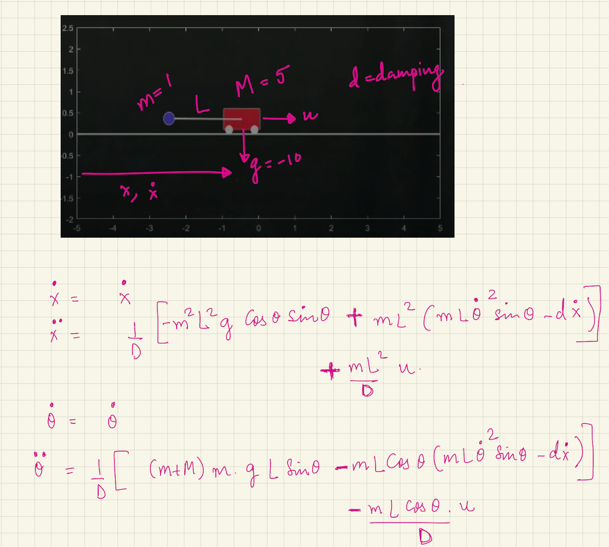

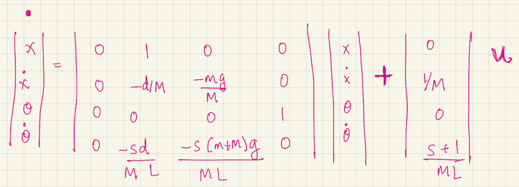

clear; clc; close all;

m = 1; M = 5; L = 2; g = -10; d = 1;

s = 1; % pendulum up (s=1), pendulum down (s=-1)

% y = [x; dx; theta; dtheta];
A = [0 1 0 0;
    0 -d/M -m*g/M 0;
    0 0 0 1;
    0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; s*1/(M*L)];

## Initial Condition

y0= [0; 0; pi; 0.5];

## Initial System Analysis

eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339


**One pole of the system is unstable!**

# **Part 2- Full state feedback Controller Design**

**Before we jump onto controller design, check for controllability. **

# **Controllability**

rank(ctrb(A,B))

ans = 4

The rank of the Controllability matrix is 4. So the system in controllable with a controller u= -kx

Let's design a controller

# Design a Controller- Pole Placement

Pole_Multiplicity= rank(B)

**Checking rank(B) before designing controller for pole placement.**

**The "place" command cannot place poles with multiplicity greater than rank(B).**

desired_eigs= [-1, -1.2, -1.3, -1.4];
K= place(A, B, desired_eigs)

K =    -2.1840   -8.2440  153.9680   63.4880


Look at the controller values! Actuators cannot achieve this! But lets worry about this later. 

## Check if system in controllable with the Controller

eig(A-B*K)

ans =    -1.4000
   -1.3000
   -1.2000
   -1.0000


y0 = [0; 0; pi; .5];
tspan = 0:.001:10;
[t,x] = ode45(@(t,x)pendcart(x,m,M,L,g,d,0),tspan,y0);
x(end,:)

ans =    -0.4536   -0.1777    4.6180   -2.7391


[t,x] = ode45(@(t,x)pendcart(x,m,M,L,g,d,-K*(x-[1; 0; pi; 0])),tspan,y0);
x(end,:)

ans =     0.9893    0.0096    3.1426   -0.0008


## Notice that the controller u= -K(x - x_desired) where xt is the full system states!

# Designing a Controller- Linear Quadratic Regulator 

Q= diag([1, 1, 10, 100]);
R= 0.01;
K= lqr(A, B, Q, R)

K =   -10.0000  -27.3028  355.4191  183.4199


eig(A-B*K)

ans =  -10.7362 + 0.0000i
  -0.7448 + 0.7307i
  -0.7448 - 0.7307i
  -0.8556 + 0.0000i


# Understanding the Controller

[Evectors, Evalues]= eig(A-B*K);
Eigen_Values= diag(real(Evalues))

Eigen_Values =   -10.7362
   -0.7448
   -0.7448
   -0.8556


**LQR understood that one eigenvalue needs to be agressive. Much much more than the others, because the penalty on that one is a lot higher. So one pole is placed at -10. This would be pole for thetadot. **

**-10 is the most stable Eigen values.**

**What is the Eigen vector corresponding to this Eigenvalue?**

Evectors(:,1)

ans =     0.0822
   -0.8824
    0.0430
   -0.4612


# What does the designed Controller tell you?

The most stabilizing direction are xdot and thetadot. 

If you want a good controller, have a good control over the variables xdot and thetadot!!

# Controllability Gramian

Gramians cannot be computed for models with unstable dynamics. So, we get them when the pendulum is in down position.

% s=-1; % 
% A = [0 1 0 0;
%     0 -d/M -m*g/M 0;
%     0 0 0 1;
%     0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];
% B = [0; 1/M; 0; s*1/(M*L)];
% 
% 
% sys= ss(A,B,[1 0 0 0],0);
% det(gram(sys,'o'))
% det(gram(sys,'c'))

**LQR does a better pole placement than you do**

**You decide the system performance and not the eigenvalues.**

[t,y] = ode45(@(t,y)pendcart(y,m,M,L,g,d,-K*(y-[1; 0; pi; 0])),tspan,y0);
y(end,:)

ans =     0.9982   -0.0011    3.1413    0.0002


# Part 3- Observer 

# Observability

This is a binary indicator whether a system is observable or not. 

But does not tell us which state we should observe. 

C = [1 0 0 0];
D = zeros(size(C,1),size(B,2));

Observability_using_position= rank(obsv(A,C))

ans = 4

**Isn't this cool? I can observe all the states of the system if I only observe the position of the cart. I can then design a full state feedback control! **


Observability_using_velocity = rank(obsv(A, [0 0 1 0]))

ans = 3

**What does this mean?**

**I cannot observe all the other states if I only measure the velocity of the cart. **

Observability_mat= obsv(A,[0 0 1 0])

Observability_mat =          0         0    1.0000         0
         0         0         0    1.0000
         0   -0.1000    6.0000         0
         0    0.0200   -0.2000    6.0000


Observability matrix columns = [x, xdot, theta, thetadot]

I cannot observe (get) the position of the cart if I measure the angle of the pendulum on the cart. 

# Observing smaller subsystem

We don't care about the position of the cart. So having it as a state is not that important. Is the smaller subsystem observable? 

s = -1; % pendulum up (s=1), pendulum down (s=-1)
% y = [x; dx; theta; dtheta];
A = [0 1 0 0;
    0 -d/M -m*g/M 0;
    0 0 0 1;
    0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; s*1/(M*L)];

Adash= A(2:end, 2:end);
Cdash= [1, 0, 0];
rank(obsv(Adash,Cdash))

ans = 3

If we measure any of velocity, theta or thetadot, the system is observable. 

# **Observability Gramian**

Observability does not tell us which state we should observe. The Gramian does!

Bdash= B(2:end);
Ddash= 0;
sys= ss(Adash,Bdash,[1 0 0],Ddash);
det(gram(sys,'o'))

ans = 50.0000

sys= ss(Adash,Bdash,[0 1 0],Ddash);
det(gram(sys,'o'))

ans = 0.0313

sys= ss(Adash,Bdash,[0 0 1],Ddash);
det(gram(sys,'o'))

ans = 0.0313

**We can observe the system much better if we can measure the velocity of the cart than any other state!!**

**Buy a sensor to measure the velocity of the cart!  **

# Part 4- Designing an observer- Kalman Filter

Designing new state space system by adding disturbance and noise into the system

When designing Kalman filter, we need to use s=-1, i.e. pendulum down condition. 

When we have both a Kalman filter and a LQR, we can use s=1 pendulum up condition. 

Why? If we are only estimating and not controlling at the same time, the inverted pendulum falls down and the linearized model fails. 

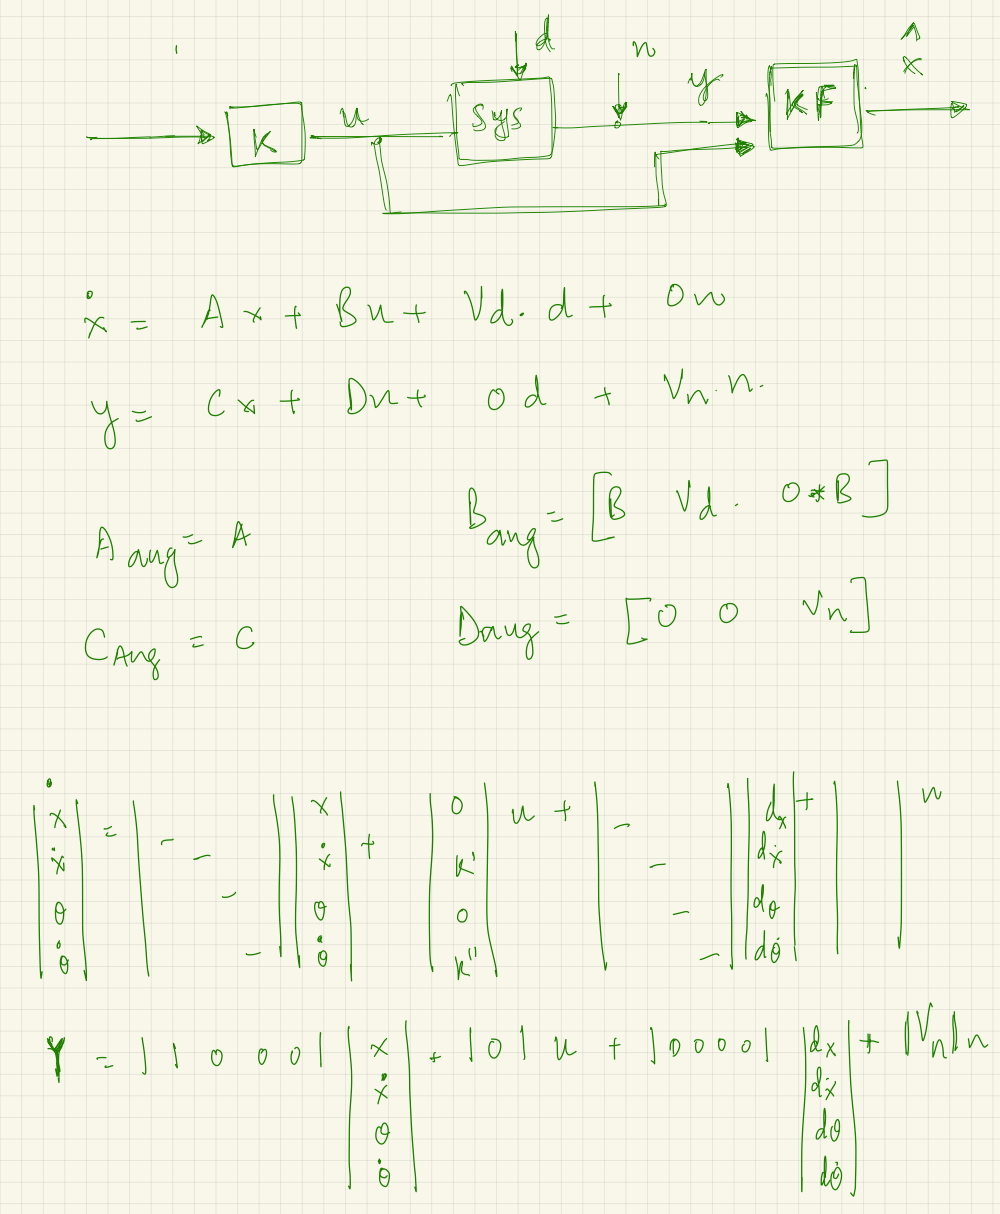

Vd= [0.1 0 0 0;
     0 0.1 0 0;
     0 0 0.1 0;
     0 0 0 0.1];
Vn= 1;

Aaug=A;
Baug= [0            0.1 0 0 0       0;
       1/M          0 0.1 0 0       0;
       0            0 0 0.1 0       0;
       s*1/(M*L)    0 0 0 0.1       0];
Caug= C;
Daug= [0 0 0 0 0 Vn];

[Kf1, P, E]= lqe(A, Vd, C, Vd, Vn)

Kf1 =     0.1458
    0.0101
   -0.0055
   -0.0020


P =     0.1458    0.0101   -0.0055   -0.0020
    0.0101    0.0144    0.0012   -0.0341
   -0.0055    0.0012    0.0171   -0.0005
   -0.0020   -0.0341   -0.0005    0.1027


E =   -0.0175 + 2.4483i
  -0.0175 - 2.4483i
  -0.1553 + 0.0982i
  -0.1553 - 0.0982i


**The one below is an alternate method to design the same Kalman filter gain matrix ('L') using the lqr command instead of lqe. They give similar result. **

Kf2= (lqr(A',C',Vd, Vn))' 

Kf2 =     0.8204
    0.2866
   -0.2281
   -0.2575


## Physical System- Measure only one state with noise and dist

In this system, we are measuring only one state of the system- the position. The output of this has included disturbance and noise. 

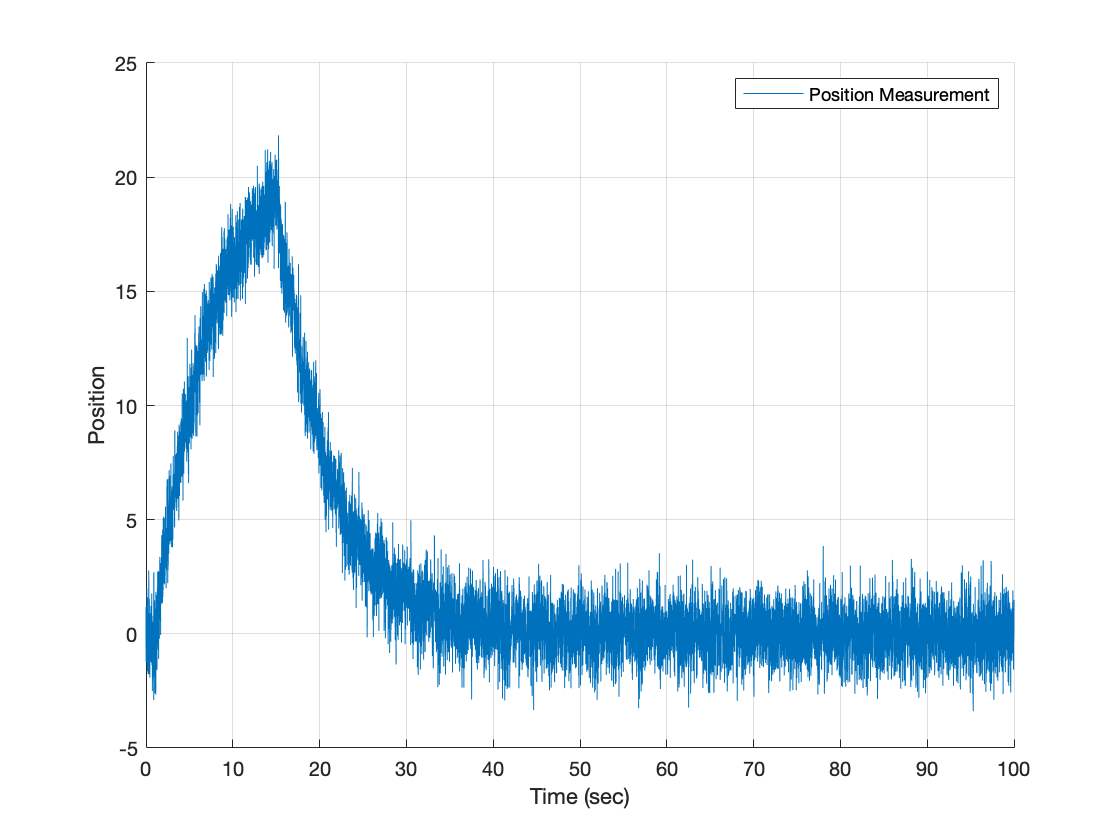

sys_partialstate= ss(Aaug, Baug, [1 0 0 0], Daug);
t= 0:0.01:100;
uDist= randn(4, size(t,2));
uNoise= randn(size(t));
u= 0*t;
u(100:120)= 100;
u(1500:1520)= -100;
uAug= [u; Vd*Vd*uDist; uNoise];
[measuredstate,t]= lsim(sys_partialstate, uAug, t);
figure; hold on; grid on; plot(t, measuredstate(:,1));
xlabel('Time (sec)');
ylabel('Position');
legend({'Position Measurement'});

## Full State System - To get underlying truth 

This is the full system. We are measuring all the states here. The output from this is the real truth. We are measuring all states **with disturbances but without noise. **

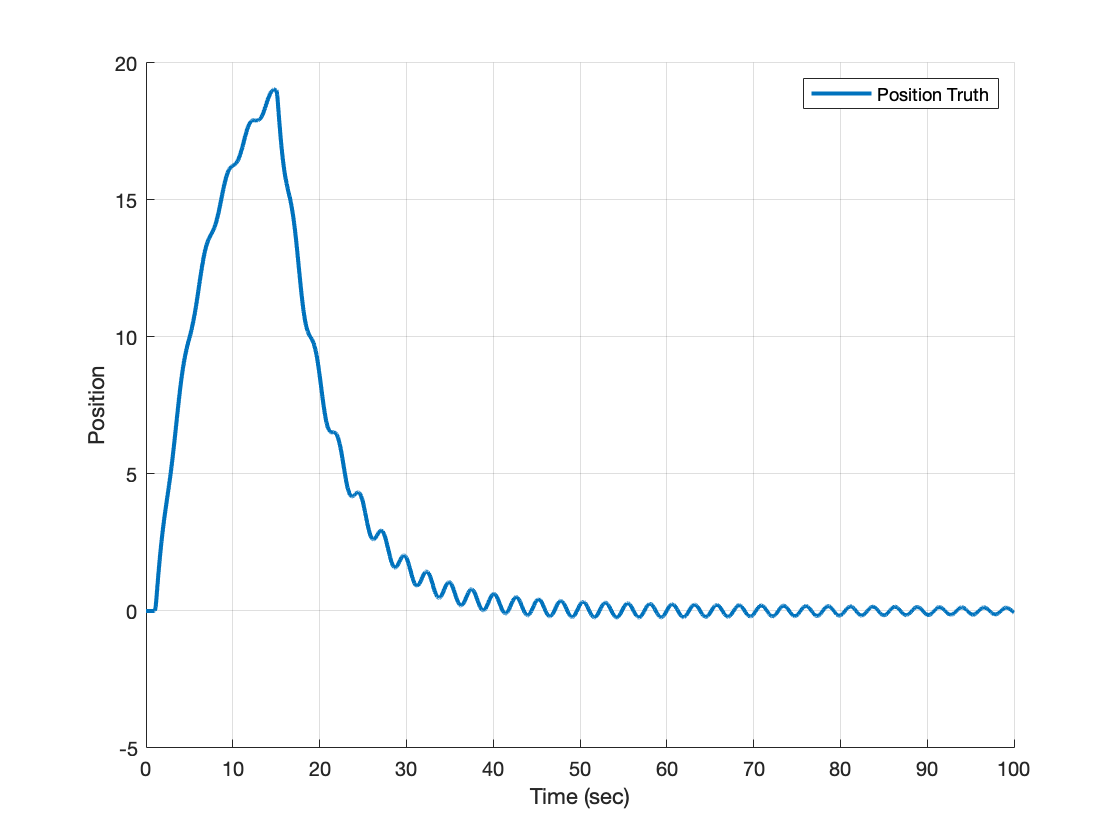

sys_fullstate= ss(Aaug, Baug, eye(4), zeros(size(eye(4),1),size(Baug,2))); 

uAug= [u; 0*Vd*Vd*uDist; 0*uNoise];
[xtrue,t]= lsim(sys_fullstate, uAug, t);
figure; hold on; grid on; plot(t, xtrue(:,1), 'LineWidth',2);
xlabel('Time (sec)');
ylabel('Position');
legend({'Position Truth'});

# Kalman Filter system

in this example, we are using a single Kalman gain because we're assuming that the linear system doesn't change.  If we are controlling a more complex system, where the linearization point is changing, or where there are nonlinear dynamics, then we update the Kalman gains as well.

This Kalman Filter system is its own dynamical system. 

It has two input signals- u and y

It predicts the state - xhat. 

A= A-Kf*C

B= [B Kf]

C= eye(4). Why? We want to measure all the states of the system. So we use an identity matrix. 

It has no feedthrough term - so D is zero. 

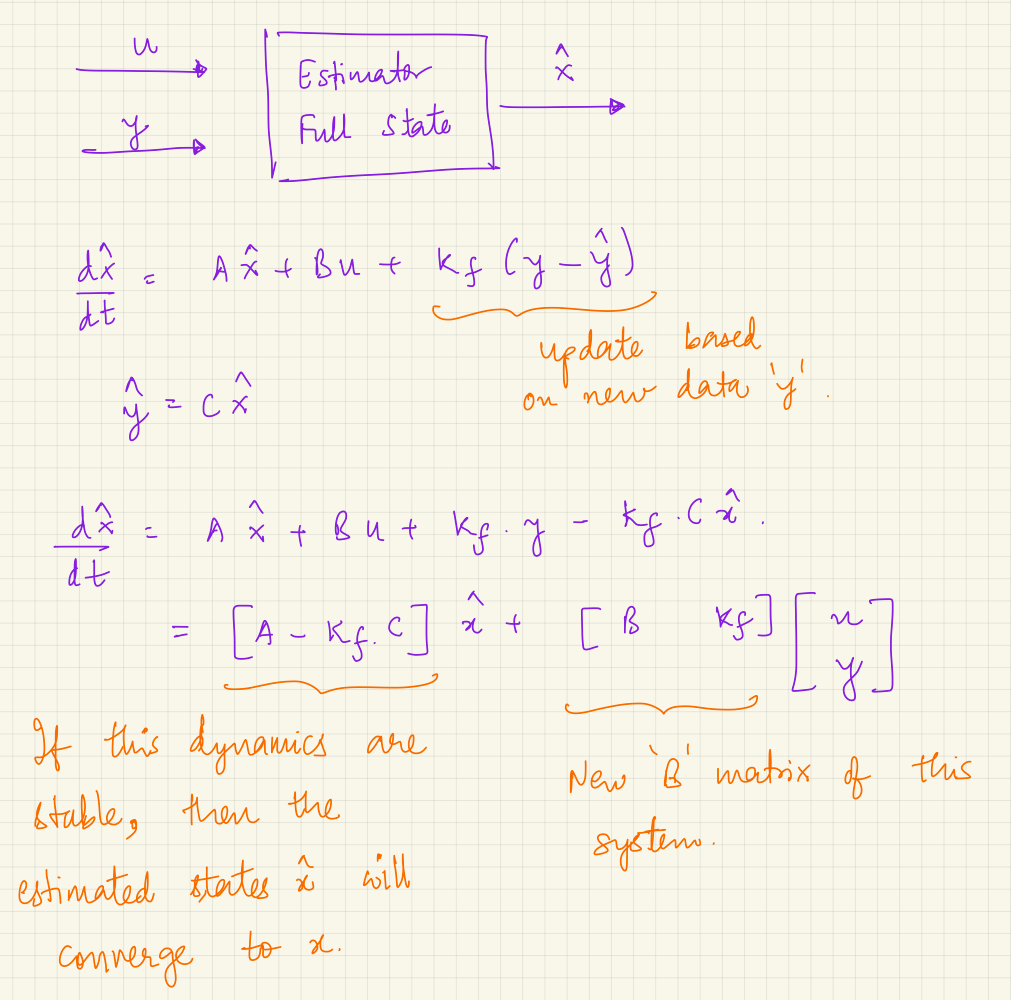

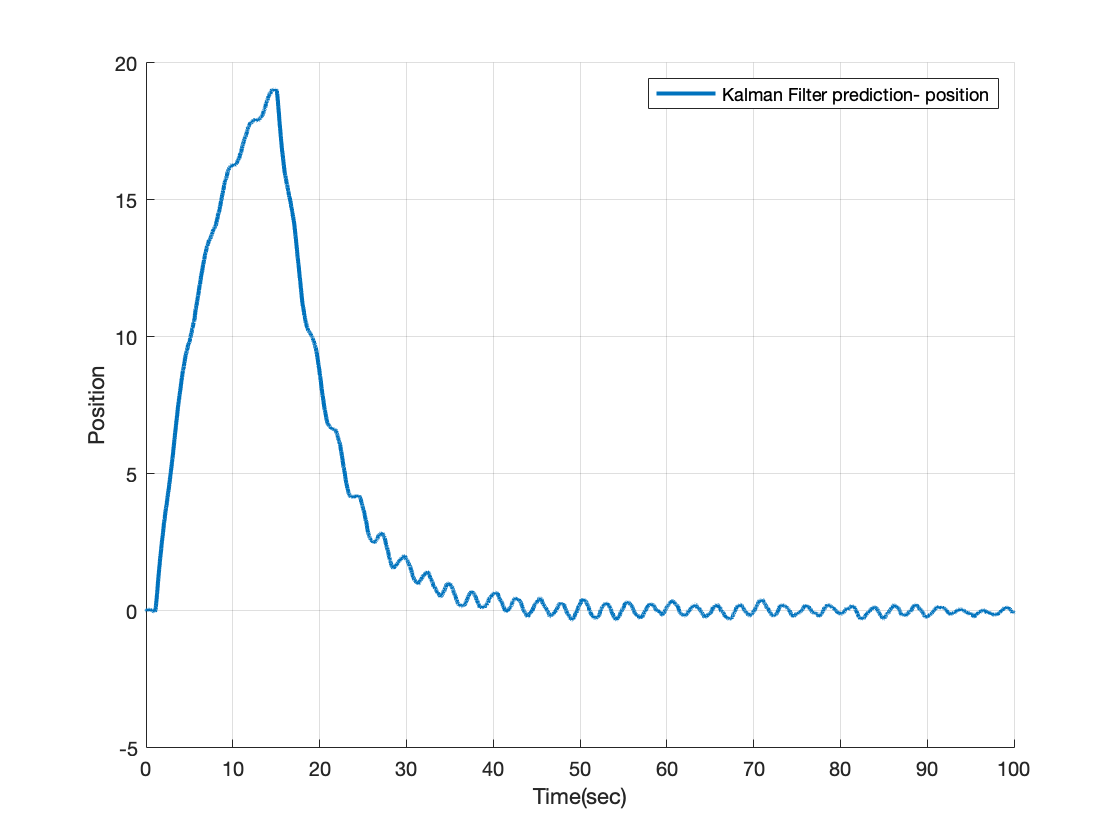

A_kf= A- Kf2*C; % A of Kalman Filter. 
B_kf= [B Kf2];
C_kf= eye(4); % Because we want to get all states from Kalman Filter
D_kf= 0*[B Kf2]; % Kalman Filter dynamical system has no feedthrough term
sysKf= ss(A_kf,B_kf, C_kf, D_kf);
[xpredicted,t]= lsim(sysKf, [u;measuredstate'], t);
figure; hold on; grid on; 
plot(t, xpredicted(:,1), 'LineWidth',2);
xlabel('Time(sec)');
ylabel('Position');
legend({'Kalman Filter prediction- position'});

# Plot all states

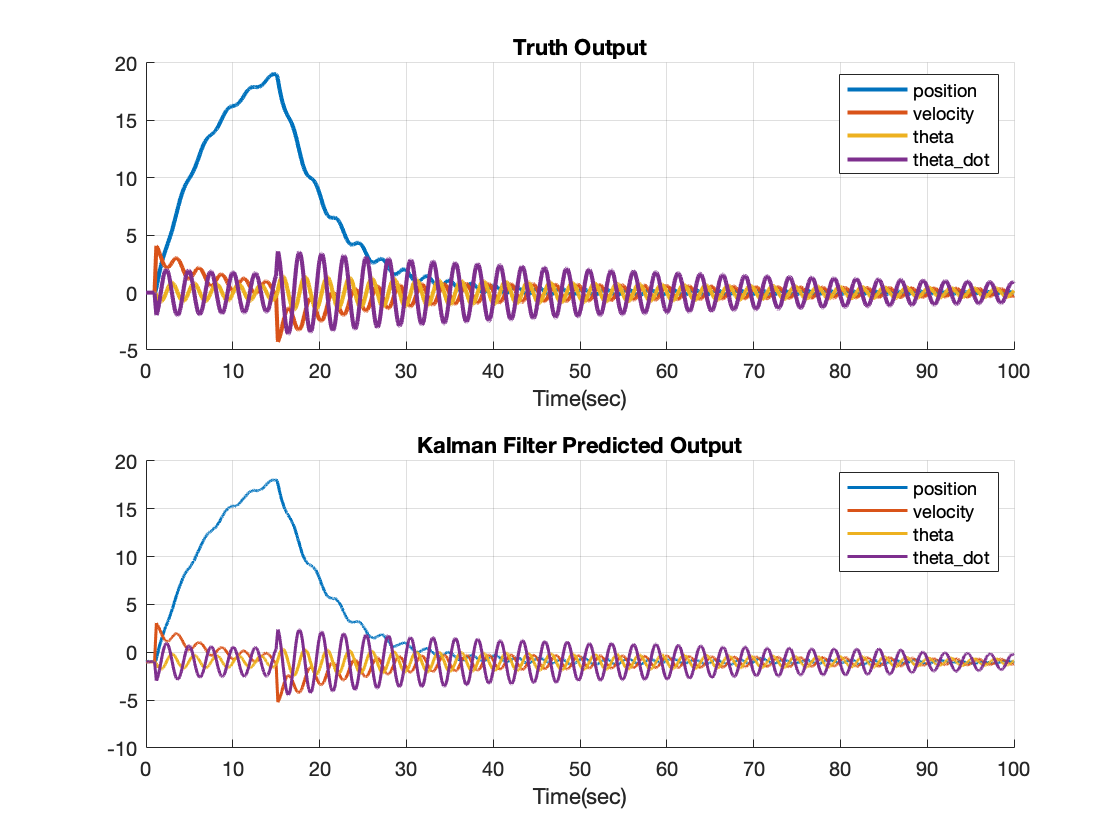

figure; 
subplot(2,1,1); hold on; grid on; 
plot(t,xtrue, 'LineWidth',2); xlabel('Time(sec)');
legend({'position', 'velocity', 'theta', 'theta\_dot'});
title('Truth Output');
subplot(2,1,2); hold on; grid on; 
plot(t, xpredicted-1, 'LineWidth', 1.5); xlabel('Time(sec)');
title('Kalman Filter Predicted Output');
legend({'position', 'velocity', 'theta', 'theta\_dot'});

**So now, we have the predicted states from Kalman Filter. We can use these predicted states to design an LQR for the pendulum cart system. **

# Part 5- Implementing LQE and LQR together 

# Functions

## Function for simulating the inverted pendulum on a cart system. 

function dx = pendcart(x,m,M,L,g,d,u)
    Sx = sin(x(3));
    Cx = cos(x(3));
    D = m*L*L*(M+m*(1-Cx^2));
    
    dx(1,1) = x(2);
    dx(2,1) = (1/D)*(-m^2*L^2*g*Cx*Sx + m*L^2*(m*L*x(4)^2*Sx - d*x(2))) + m*L*L*(1/D)*u;
    dx(3,1) = x(4);
    dx(4,1) = (1/D)*((m+M)*m*g*L*Sx - m*L*Cx*(m*L*x(4)^2*Sx - d*x(2))) - m*L*Cx*(1/D)*u;
end